clc;
clear;

% Load training data and labels
train_data_x = load('data_train.mat');
train_data_y = load('data_train_labels.mat');
train_data_x = train_data_x.data_train;
train_data_y = train_data_y.data_train_labels;

% Define label names
label_names = {'normal', 'roller', 'inner', 'outer', ...
               'inner+roller', 'outer+inner', 'outer+inner+roller', 'outer+roller'};

% Use 'data_train_labels' as your target labels
target_labels = train_data_y';

% Define parameters for your dataset (adjust these based on your specifications)
theta = 14.94 * pi / 180; % Convert contact angle from degrees to radians
n = 17;
d = 0.01; % in meters
D = 0.06; % in meters
fi = 800 / 60; % Convert rpm to Hz

% Preallocate feature matrix
num_columns = numel(train_data_x);
num_features = 5; % Including mean, std, rms, skewness, kurtosis, 1st harmonic, 2nd harmonic, crest factor, impulse factor, and clearance factor
time_domain_features = zeros(num_columns, num_features);

% Compute and populate the time domain feature matrix
for col = 1:num_columns
    data = train_data_x{col};
    %mean_value = mean(data);
    std_deviation = std(data);
    rms_value = rms(data);
    mav_value = mean(abs(data));
    skewness_value = skewness(data);
    kurtosis_value = kurtosis(data);
    fft_data = fft(data);
    N = length(data);
    fft_normalized = abs(fft_data/N);
    % first_order_harmonic = fft_normalized(2);
    % second_order_harmonic = fft_normalized(3);
    crest_factor = max(data) / rms_value;
    % impulse_factor = max(data) / mean(abs(data));
    % clearance_factor = max(data) / (max(data) - min(data));
    p2p=max(data)-min(data);
    bin_indices = (0:N-1)';
    spectral_centroid_bin = sum(bin_indices .* fft_normalized) / sum(fft_normalized);
    shape_factor = rms_value / mav_value;
    zero_crossings = sum(abs(diff(data > 0))) / length(data);
    waveform_length = sum(abs(diff(data)));
    rms_mav_index = rms_value / mav_value;
    time_domain_features(col, :) = [skewness_value,rms_value,std_deviation,zero_crossings,waveform_length];
end

% Perform k-fold cross-validation
k = 5; % Number of folds
cv = cvpartition(numel(target_labels), 'KFold', k);

% Display the partitioning of k-fold and the number of data in each fold
disp('Partitioning of K-Fold Cross-Validation:');

Partitioning of K-Fold Cross-Validation:


for i = 1:k
    train_idx = training(cv, i);
    val_idx = test(cv, i);
    disp(['Fold ', num2str(i), ': Training Set - ', num2str(sum(train_idx)), ' samples, Validation Set - ', num2str(sum(val_idx)), ' samples']);
end

Fold 1: Training Set - 1639 samples, Validation Set - 409 samples
Fold 2: Training Set - 1638 samples, Validation Set - 410 samples
Fold 3: Training Set - 1638 samples, Validation Set - 410 samples
Fold 4: Training Set - 1638 samples, Validation Set - 410 samples
Fold 5: Training Set - 1639 samples, Validation Set - 409 samples




% Initialize variables to store evaluation metrics
accuracy_rf = zeros(k, 1);
conf_matrices_rf = cell(k, 1);

for i = 1:k
    % Training set
    train_idx = training(cv, i);
    train_features = time_domain_features(train_idx, :);
    train_labels = target_labels(train_idx);
    
    % Validation set
    val_idx = test(cv, i);
    val_features = time_domain_features(val_idx, :);
    val_labels = target_labels(val_idx);
    
    % Train Random Forest Classifier
    target_labels_str = arrayfun(@(x) label_names{x}, train_labels, 'UniformOutput', false);
    nTrees = 100;
    rfModel = TreeBagger(nTrees, train_features, target_labels_str, 'Method', 'classification');
    
    % Predict labels for validation set
    predicted_labels_rf = predict(rfModel, val_features)';
    
    % Evaluate performance
    conf_matrices_rf{i} = confusionmat(label_names(val_labels), predicted_labels_rf, 'Order', label_names);
    accuracy_rf(i) = sum(strcmp(predicted_labels_rf, label_names(val_labels))) / numel(val_labels);
    for j = 1:numel(label_names)
        TP = conf_matrices_rf{i}(j, j);
        FP = sum(conf_matrices_rf{i}(:, j)) - TP;
        FN = sum(conf_matrices_rf{i}(j, :)) - TP;
        TN = sum(conf_matrices_rf{i}(:)) - TP - FP - FN;

        precision_rf(i, j) = TP / (TP + FP);
        recall_rf(i, j) = TP / (TP + FN);
        f1Scores_rf(i, j) = 2 * ((precision_rf(i, j) * recall_rf(i, j)) / (precision_rf(i, j) + recall_rf(i, j)));
    end
end


% Calculate average performance metrics for Support Vector Machine (SVM)
avg_accuracy_rf = mean(accuracy_rf);
avg_precision_rf = mean(precision_rf, 1);
avg_recall_rf = mean(recall_rf, 1);
avg_f1Scores_rf = mean(f1Scores_rf, 1);


% Display k-fold cross-validation results for Support Vector Machine (SVM)
disp("Random Forest (RF) Results:");

Random Forest (RF) Results:


disp(['Average Accuracy: ', num2str(avg_accuracy_rf * 100), '%']);

Average Accuracy: 99.9024%


disp('Average Precision:');

Average Precision:


disp(avg_precision_rf);

    1.0000    0.9958    1.0000    1.0000    0.9962    1.0000    1.0000    1.0000



disp('Average Recall:');

Average Recall:


disp(avg_recall_rf);

    0.9955    1.0000    1.0000    1.0000    1.0000    0.9950    1.0000    1.0000



disp('Average F1-Score:');

Average F1-Score:


disp(avg_f1Scores_rf);

    0.9977    0.9979    1.0000    1.0000    0.9981    0.9975    1.0000    1.0000




% Display k-fold cross-validation results for Random Forest
disp("For Random Forest, Number of Trees: 100, Number of Features: 5 ")

For Random Forest, Number of Trees: 100, Number of Features: 5 


disp(['Average Accuracy: ', num2str(avg_accuracy_rf * 100), '%']);

Average Accuracy: 99.9024%


disp('Confusion Matrices:');

Confusion Matrices:


Fold 1


    51     0     0     0     0     0     0     0
     0    54     0     0     0     0     0     0
     0     0    59     0     0     0     0     0
     0     0     0    41     0     0     0     0
     0     0     0     0    53     0     0     0
     0     0     0     0     0    60     0     0
     0     0     0     0     0     0    47     0
     0     0     0     0     0     0     0    44



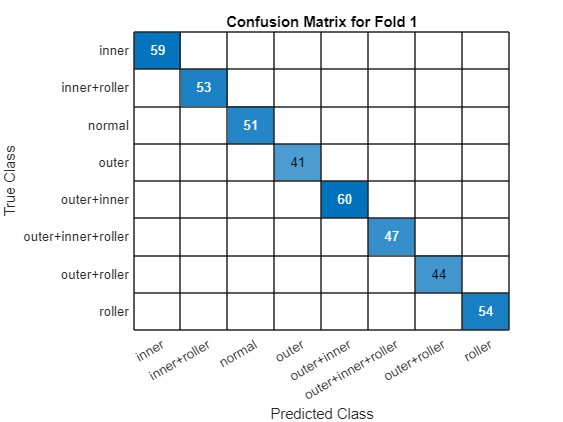

Fold 2


    44     0     0     0     0     0     0     0
     0    54     0     0     0     0     0     0
     0     0    39     0     0     0     0     0
     0     0     0    45     0     0     0     0
     0     0     0     0    60     0     0     0
     0     0     0     0     0    45     0     0
     0     0     0     0     0     0    65     0
     0     0     0     0     0     0     0    58



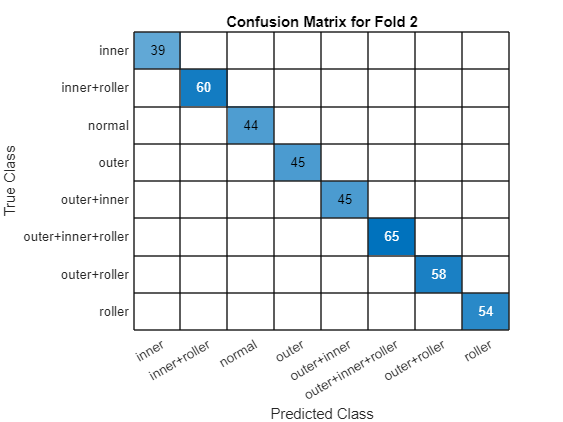

Fold 3


    58     0     0     0     0     0     0     0
     0    46     0     0     0     0     0     0
     0     0    59     0     0     0     0     0
     0     0     0    60     0     0     0     0
     0     0     0     0    51     0     0     0
     0     0     0     0     1    39     0     0
     0     0     0     0     0     0    40     0
     0     0     0     0     0     0     0    56



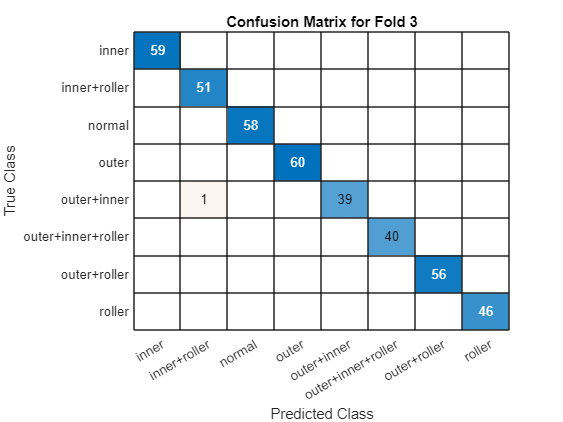

Fold 4


    43     1     0     0     0     0     0     0
     0    47     0     0     0     0     0     0
     0     0    61     0     0     0     0     0
     0     0     0    57     0     0     0     0
     0     0     0     0    43     0     0     0
     0     0     0     0     0    50     0     0
     0     0     0     0     0     0    58     0
     0     0     0     0     0     0     0    50



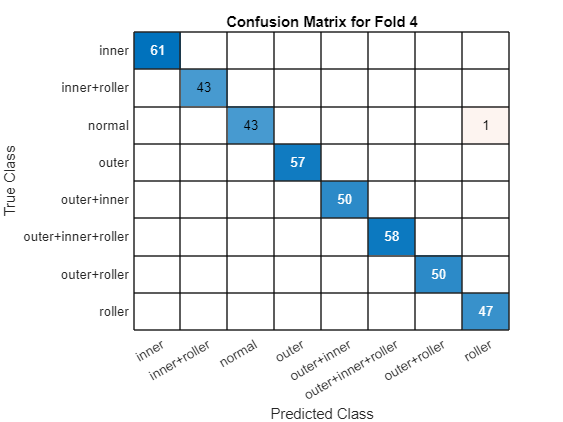

Fold 5


    59     0     0     0     0     0     0     0
     0    55     0     0     0     0     0     0
     0     0    38     0     0     0     0     0
     0     0     0    53     0     0     0     0
     0     0     0     0    49     0     0     0
     0     0     0     0     0    61     0     0
     0     0     0     0     0     0    46     0
     0     0     0     0     0     0     0    48



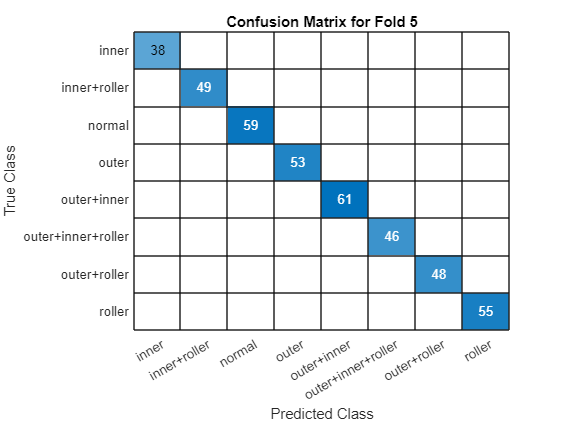

for i = 1:k
    disp(['Fold ', num2str(i)]);
    disp(conf_matrices_rf{i});
    
    % Create confusion matrix plot
    figure;
    confusionchart(conf_matrices_rf{i}, label_names);
    title(['Confusion Matrix for Fold ', num2str(i)]);
end